# Signal Modifier

Below code opens sample simulink model of this block

sig_mod_block_6

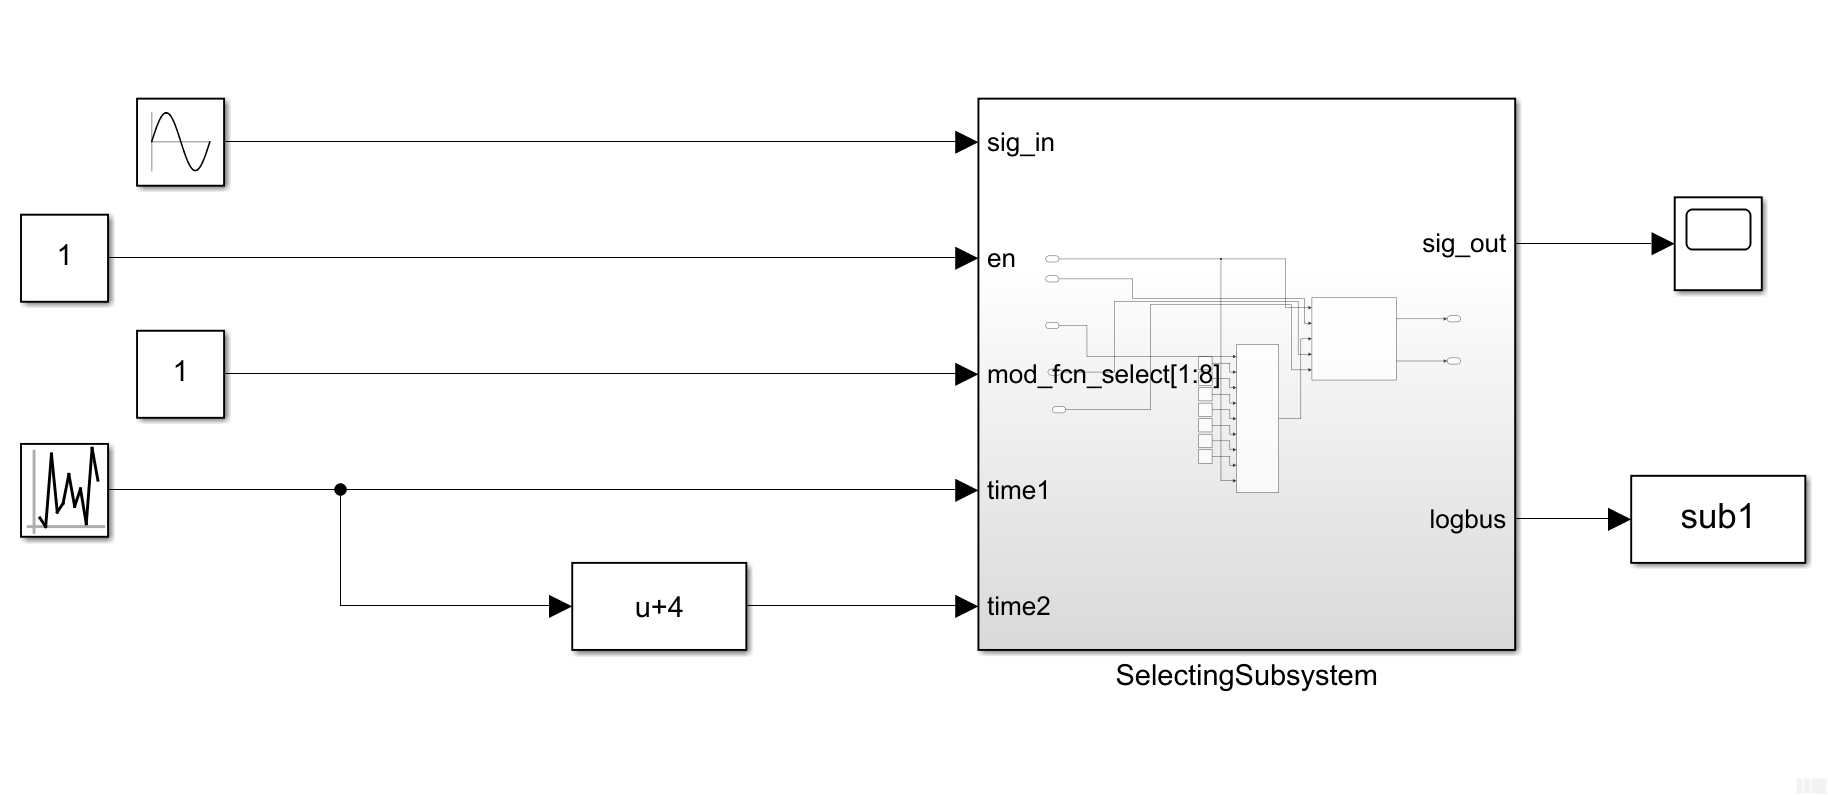

## How it works

The block replaces the input signal with the modification function between each time-interval pair `t1 t2`. In the above sample, the output signal is switched between values of the input signal and the first modification function preset (a step function, transitioning from 0 to 1 at 5 seconds).

Double click the scope block attached to *sig_out *to open the scope view. Then run the simulation to observe the signal modifier's effect on the input sine function.

sim('sig_mod_block_6');
open_system('sig_mod_block_6/Scope');

## `sig_in` and `en` inports

*sig_in* is the input signal to be modified. In this example case, a simple sine function. 

`en` is the enable. The block performs its signal modification when `en=1`. When `en=0` the block doesn't modify the input signal, making `sig_in=sig_out`

Double click on the constant block attached to the *en* inport to change the value.

set_param('sig_mod_block_6/Constant3','Value','1');

Double click the scope block attached to *sig_out *to open the scope view. Then run the simulation to observe the signal modifier's effect on the input sine function.

sim('sig_mod_block_6');
open_system('sig_mod_block_6/Scope');

## `mod_fcn_select[1:8]`

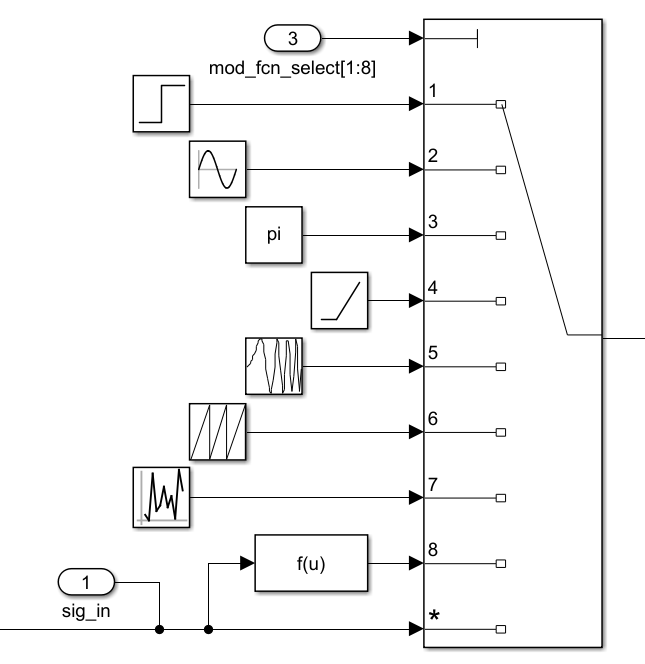

This is a view of inside the SelectingSubsystem (parent) block. The `mod_fcn_select[1:8]` input is used to select from preset modification functions (shown above). These are the functions that the input signal `sig_in` will be modified by. `mod_fcn_select[1:8]` can take on integer values from 1 to 8 to select one of the 7 preset modification functions or a modified version of the input signal (option 8). If `mod_fcn_select[1:8]` takes on another value, the default modification function will be selected (in this case `sig_in`, which effectively ensures no modification to the input signal). 

set_param('sig_mod_block_6/Constant1','Value','8');

Double click on the *SelectingSubsystem > ModPresetSubsystem* subsystems to access these presets.

open_system('sig_mod_block_6/SelectingSubsystem/ModPresetSubsystem');

Double click on any of the preset modification functions to change their parameters.

open_system('sig_mod_block_6/SelectingSubsystem/ModPresetSubsystem/Fcn');

Double click the scope block attached to *sig_out *to open the scope view. Then run the simulation to observe the signal modifier's effect on the input sine function.

sim('sig_mod_block_6');
open_system('sig_mod_block_6/Scope');

## Replace Mode Operation and Adjust Mode Operation (`mod_fcn_select[1:8] == 8`)

Simply, the signal modifier block can either replace the input signal with the modifying signal at certain time intervals, or adjust the input signal using the modifying signal at certain time intervals.

Double click the block *f(u) *attached to input 8 shown above to edit how the input signal will be adjusted.

open_system('sig_mod_block_6/SelectingSubsystem/ModPresetSubsystem/Fcn');

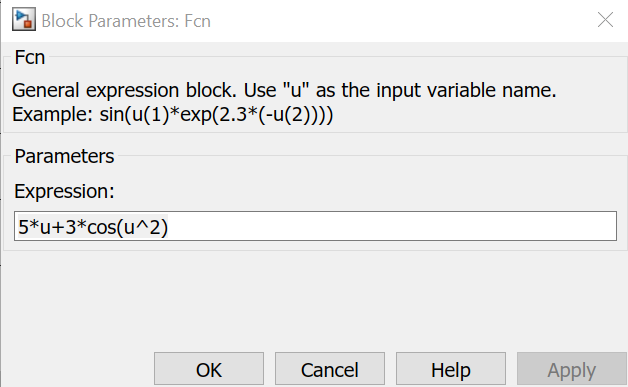

`u` represents the original input signal. For example, `u(10)` in the expression box shown is equivalent to `sin(10)`, because in our case the input signal is the basic sine function.

The sample expression above is equivalent to `5*sin(t) + 3*cos((sin(t))^2) `since the input signal is the basic sine function.

## `time1` and `time2`

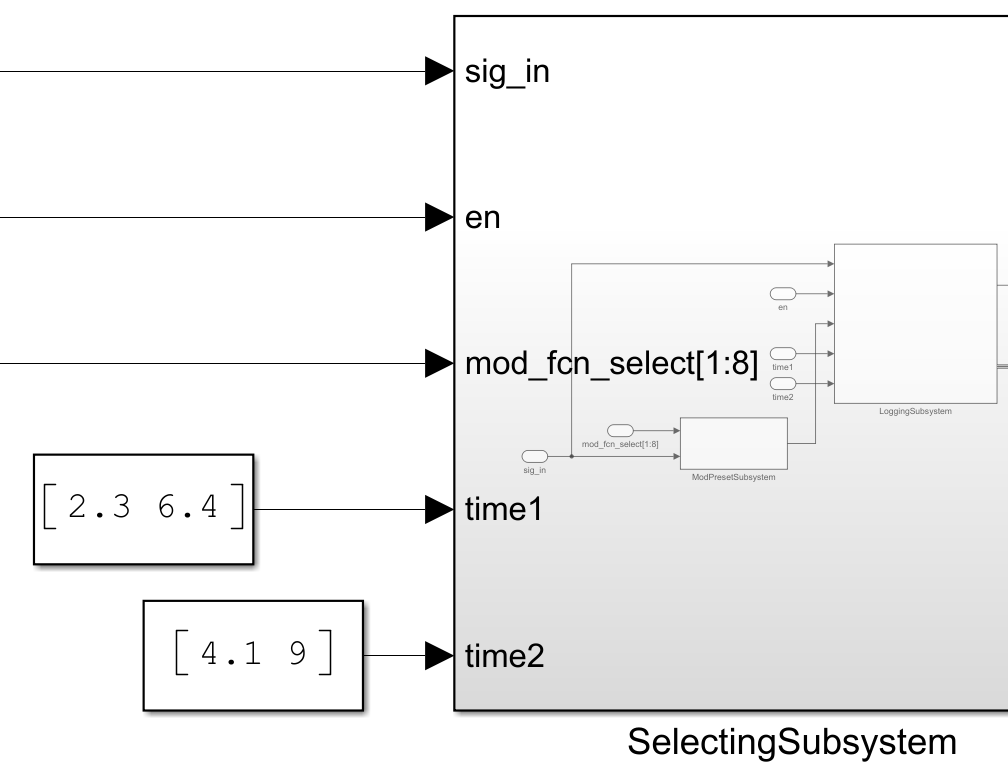

set_param('sig_mod_block_6/Constant','Value','[2.3 6.4]'); % vector of start times
set_param('sig_mod_block_6/Constant2','Value','[4.1 9]'); % vector of end times

## Logging and Output